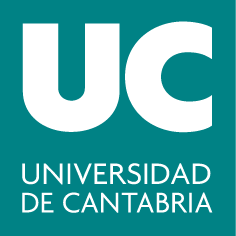

#### ***Grado en Ingeniería ****de los Recursos Energéticos / ****Grado en Ingeniería ****de los Recursos Mineros*

## **Álgebra Lineal y Geometría**

# **Práctica 3: Espacio Euclídeo**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Objetivos	

- Hallar una base ortonormal de un subespacio y entender la noción de ortogonalidad y normalización.

- Hallar la proyección de un vector sobre un supespacio usando la matriz de proyección.

- Aproximar la solución de un sistema incompatible con el método de mínimos cuadrados.

- Ajustar una nube de puntos a una función polinómica o exponencial mediante el método de mínimos cuadrados.

### Comandos útiles

- `dot(u, v)`: producto escalar habitual de dos vectores. Ejemplo:

dot([1,2], [2,3])

ans = 8

- `norm(v): `devuelve el módulo o norma del vector `v`.

norm([3 4 0])

ans = 5

Efectivamente, podemos comprobar que la norma es la raíz cuadrada del producto escalar de un vector por sí mismo:

sqrt(dot([3 4 0], [3 4 0]))

ans = 5

- `null(A)`: Devuelve la solución al sistema de ecuaciones homogéneo de matriz de coeficientes `A (Ax=b)`. Cuando no se acompaña del argumento `'r',`equivale a obtener una **base ortonormal** de un subespacio dado por la matriz A (con los coeficientes de las implícitas por filas). Ver la práctica 1 para la interpretación del resultado de `null`.

A = [1 0 1;-4 5 0]; 
H=null(A) 

H =    -0.6155
   -0.4924
    0.6155


Se comprueba que es ortonormal de dos maneras:

H(1,1)^2+H(2,1)^2 + H(3,1)^2 

ans = 1

norm(H)

ans = 1

- `orth`: Para **ortonormalizar** una matriz. Halla una base ortonormal de la imagen (rango) de una matriz A, es decir, si los vectores columna que se le pasan a `orth` no fuesen linealmente independientes, la propia función se encarga de eliminar los que sean dependientes y ortonormaliza el resto. Ejemplo:

A = [1 0 -1;-2 1 3; 0 1 -1];
AO=orth(A) % El número de columnas de AO es igual al rango de A.

AO =    -0.3387   -0.1056   -0.9350
    0.9280   -0.2012   -0.3134
   -0.1550   -0.9738    0.1662


B = [1 0 1;-2 1 -2; 0 1 0]; % 1ª y 3ª columnas iguales
BO=orth(B)

BO =    -0.4082   -0.4082
    0.9082   -0.0918
    0.0918   -0.9082


Se comprueba que BO es ortonormal (cada uno tiene norma 1 y los vectores son ortogonales dos a dos):

[norm(BO(:,1)) norm(BO(:,2))]

ans =     1.0000    1.0000


dot(BO(:,1),BO(:,2))

ans = -8.3267e-17

- `format`: Cambia el formato de los resultados.

format rat % Para tener el resultado en formato de cociente (ratio)
format long % Para recuperar el formato decimal con 15 decimales
format short % Para recuperar el formato decimal con 4 decimales

- `exp(x)`: exponencial de x, es decir, eleva `e` a `x`.

#### Comandos para ajustar un conjunto de datos a un polinomio

- `polyfit(X,Y,N)`: Para ajustar una nube de puntos (X,Y) a un polinomio de orden `N` mediante el metodo de mínimos cuadrados. Devuelve los coeficientes de las potencias en **orden decreciente**.

P= polyfit(A(1,:), A(2,:),2) % Interpretación: P(x) = P(1)*x^2 + P(2)*x + P(3)

P =    -0.5000   -2.5000    1.0000


- `polyval(P,X)`: Para evaluar un polinomio P (ajustado con `polyfit`) en un vector X:

polyval(P,[0:0.1:2])

ans =     1.0000    0.7450    0.4800    0.2050   -0.0800   -0.3750   -0.6800   -0.9950   -1.3200   -1.6550   -2.0000   -2.3550   -2.7200   -3.0950   -3.4800   -3.8750   -4.2800   -4.6950   -5.1200   -5.5550   -6.0000


#### Comandos para representaciones gráficas

- `plot(x, y,'s')`: dibuja una línea que une los puntos de abscisas en el vector x y ordenadas y, usando el estilo indicado en 's'. 's' puede ser una cadena de caracteres que indica el color (letra del nombre en inglés) o estilo de los puntos. Ver `help plot` para más detalles en los estilos. Usaremos `plot` para representar funciones en forma explícita. Ejemplo:

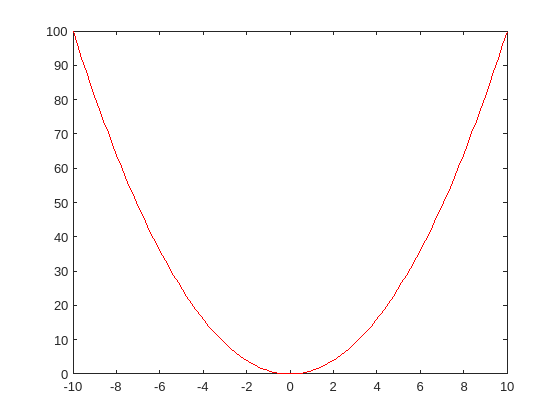

x=linspace(-10,10);
y=x.^2;
plot(x, y, 'r') % pinta el vector x frente al vector y en color rojo ('r').

- `ezplot(f, [a,b])`: dibuja la gráfica de una función simbólica en el dominio. Se utiliza, sobre todo, para representar funciones en forma implícita. La forma más fácil de introducir `f` es usando el formato string (entre comillas). `ezplot` no permite ajustar el color u otras características, para ello usamos la función `set`. Ejemplo:

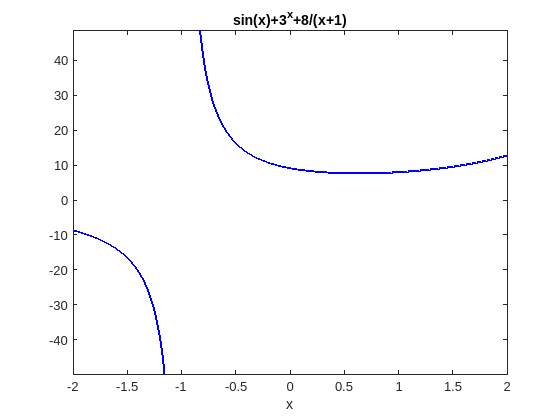

h1 = ezplot('sin(x)+3^x+8/(x+1)',[-2,2]);
set(h1,'Color','b','LineWidth',2)

- `title('string')`: Para escribir un título en la parte superior de la figura con el texto en 'string'.

- `legend('string1','string2','string3',…)`: Para incluir una leyenda en la figura, identificando en cada cadena de caracteres lo que se muestra en la figura, en el orden en que se incluyen en la gráfica.

- `grid on / grid off`: Para poner o quitar la cuadrícula del fondo de una figura.

- `axis equal`: Para igualar la escala de todos los ejes coordenados para que la proporción sea 1:1.

- `hold on`: Permite seguir dibujando en la misma figura hasta que aparezca `hold off`.

### Ejercicios resueltos

*Nota: las lineas de código que terminan en *`;`* no muestran resultado por pantalla, mientras que la mayoría sí lo muestran, para facilitar vuestra comprobación.*

#### **Ejercicio 1: Proyecciones ortogonales**

Sea S un subespacio de $\mathbb{R}^5$ determinado por las siguientes ecuaciones implícitas: 


$$S\equiv \lbrace(x, y, z, t, r) /  10x-22y+32z-7t+4r=0,11x-3y+11z-4t-27r=0,3x-y+9z-8t+14r=0 \rbrace$$


a) Hallar una base ortonormal de $S$.

b) Hallar la matriz de proyección asociada a $S$.

c) Hallar la componente del vector $\vec{v}=(1,-3,10,4,7)$ sobre $S$.

d) Hallar la proyección de $\vec{v}$ sobre el subespacio complementario ortogonal de $S$.

a) Hallar una base ortonormal de $S$.

Dado que tenemos la forma implícita de $S$ usamos `null` sobre la matriz de los coeficientes de las ecuaciones implícitas:

A=[10 -22 32 -7 4; 11 -3 11 -4 -27; 3 -1 9 -8 14];
BaseS=null(A, 'r')

BaseS =    -0.5016    5.3665
    1.1808   -2.6759
    1.1873   -3.6417
    1.0000         0
         0    1.0000


En columnas obtenemos los vectores de una base, por lo tanto, dim(S)=2. Vamos a comprobar si la base obtenida es ortonormal:

dot(BaseS(:,1), BaseS(:,2)) % para comprobar ortogonalidad

ans = -10.1754

[norm(BaseS(:,1)), norm(BaseS(:,2))] % para ver si están normalizados

ans =     2.0138    7.0867


**No** es una base ortogonal ni los vectores estan normalizados, por tanto, no es una base ortonormal. 

En cambio:

BaseOrtS=null(A) 

BaseOrtS =     0.8246   -0.2561
    0.0626    0.5858
   -0.1284    0.5907
    0.5091    0.4923
    0.2012   -0.0017


Se puede comprobar que la base obtenida es ortonormal:

dot(BaseOrtS(:,1), BaseOrtS(:,2)) % para comprobar ortogonalidad

ans = 1.1102e-16

[norm(BaseOrtS(:,1)), norm(BaseOrtS(:,2))] % para ver si estan normalizados

ans =      1     1


**Nota**: se utiliza `null` cuando conocemos la forma implícita de un subespacio, pero si ya tenemos una base (o la forma paramétrica) de un subespacio, se obtiene una base ortonormal con `orth`.

b) Hallar la matriz de proyección asociada a $S$.

Conocida una base de $S$, hallamos la matriz de proyección del subespacio $S$:

MPS=BaseS*inv(BaseS'*BaseS)*BaseS'

MPS =     0.7455   -0.0984   -0.2571    0.2937    0.1664
   -0.0984    0.3471    0.3380    0.3203    0.0116
   -0.2571    0.3380    0.3654    0.2254   -0.0268
    0.2937    0.3203    0.2254    0.5015    0.1016
    0.1664    0.0116   -0.0268    0.1016    0.0405


Si hallamos la matriz de proyección a partir de una base ortonormal, obtenemos la misma (es única e independiente de la base de $S$):

MPS=BaseOrtS*inv(BaseOrtS'*BaseOrtS)*BaseOrtS'

MPS =     0.7455   -0.0984   -0.2571    0.2937    0.1664
   -0.0984    0.3471    0.3380    0.3203    0.0116
   -0.2571    0.3380    0.3654    0.2254   -0.0268
    0.2937    0.3203    0.2254    0.5015    0.1016
    0.1664    0.0116   -0.0268    0.1016    0.0405


 Comprobamos que es cuadrada, simétrica e idempotente.

MPS-MPS^2 % idempotente

ans = 1.0e-15 *

    0.2220    0.0555         0    0.1110    0.0555
    0.0416   -0.0555   -0.0555   -0.0555    0.0052
         0   -0.0555         0   -0.0555   -0.0069
    0.0555         0         0         0    0.0278
    0.0555    0.0121    0.0139    0.0278    0.0069


c) Hallar la componente del vector $\vec{v}=(1,-3,10,4,7)$ sobre $S$.

v=[1 -3 10 4 7]'; 
h=MPS*v

h =     0.8089
    3.6026
    3.0965
    4.3044
    0.5531


d) Hallar la proyección de $\vec{v}$ sobre el subespacio complementario ortogonal de $S$.

Se puede calcular directamente como la diferencia entre $\vec{v}$ y la proyección sobre $S$:

p=v-h % p=Proyección de v sobre el complemento ortogonal de S

p =     0.1911
   -6.6026
    6.9035
   -0.3044
    6.4469


O bien hallando una base del complemento ortogonal y la matriz de proyección asociada. Una base del complemento ortogonal vendrá dado por los $(x,y,z, t, r) \in S^{\perp}$ tales que el producto escalar por los vectores de una base de $S$ es cero, es decir $\vec{v}_{1} \cdot (x,y,z,t,r)=0, \vec{v}_{2} \cdot (x,y,z,t,r)=0$, siendo en este caso $\vec{v}__1, \vec{v}_2$ los dos vectores de una base de $S$. Hallar los $(x,y,z, t, r) $ que lo verifican equivale a resolver el sistema homogéneo $A\vec{x}=\vec{0}$, donde la matriz de coeficientes tiene en sus **filas** los vectores de la base de $S$:

BaseCOS=null(BaseS','r')

BaseCOS =     0.2249   -0.5358   -0.2364
   -0.9100   -1.0745   -0.1004
    1.0000         0         0
         0    1.0000         0
         0         0    1.0000


La dimensión de $S^{\perp}$ es 3, dado que hay 3 columnas. Era esperable porque la dimensión de $S$ es 2 y estamos en $\mathbb{R}^5$ (dos subespacios complementarios deben estar en suma directa y completar el espacio total). Tambien podríamos calcular una base ortogonal del complemento ortogonal de $S$:

BaseOrtCOS=null(BaseS')

BaseOrtCOS =     0.3386   -0.3181   -0.1967
   -0.4157   -0.6842   -0.1089
    0.7946    0.0021    0.0571
   -0.2827    0.6459   -0.0378
   -0.0357   -0.1160    0.9720


Se puede comprobar que los vectores de la base de $S$ y los de la base de $S^{\perp}$ son ortogonales, tanto si consideramos la base ortonormal o la base no ortonormal:

BaseS'*BaseCOS

ans = 1.0e-04 *

   -0.0076    0.0610    0.0119
    0.0280   -0.2055    0.0980


BaseS'*BaseOrtCOS

ans = 1.0e-15 *

   -0.1110    0.1110    0.1041
   -0.3886   -0.0694         0


Hallamos la matriz de proyeccion asociada a $S^{\perp}$, bien a partir de la base no ortonormal, o bien a partir de la base ortonormal:

MPCOS=BaseCOS*inv(BaseCOS'*BaseCOS)*BaseCOS'

MPCOS =     0.2545    0.0984    0.2571   -0.2937   -0.1664
    0.0984    0.6529   -0.3380   -0.3203   -0.0116
    0.2571   -0.3380    0.6346   -0.2254    0.0268
   -0.2937   -0.3203   -0.2254    0.4985   -0.1016
   -0.1664   -0.0116    0.0268   -0.1016    0.9595


MPCOS=BaseOrtCOS*inv(BaseOrtCOS'*BaseOrtCOS)*BaseOrtCOS' 

MPCOS =     0.2545    0.0984    0.2571   -0.2937   -0.1664
    0.0984    0.6529   -0.3380   -0.3203   -0.0116
    0.2571   -0.3380    0.6346   -0.2254    0.0268
   -0.2937   -0.3203   -0.2254    0.4985   -0.1016
   -0.1664   -0.0116    0.0268   -0.1016    0.9595


p=MPCOS*v 

p =     0.1912
   -6.6026
    6.9036
   -0.3044
    6.4469


#### **Ejercicio 2: Aproximar la solución de un sistema incompatible**

Dado el siguiente sistema:


$$
    	\textstyle \left\{ \begin{array}{rcr}
   	 	2x + 3y & = &0 \\ 
 	 	x & = &1\\ 
 	 	y & = &1
   		\end{array}\right.
	$$


a) Comprobar que es un sistema incompatible.

b) Calcular la solución del sistema por mínimos cuadrados.

c) Estimar el error cuadrático cometido. 

Creamos la matriz de coeficientes, la matriz ampliada y el vector de términos independientes.

A=[2 3; 1 0; 0 1];
b=[0 1 1]';
Ampli=[A b];

a) Comprobar que es un sistema incompatible.

[rank(A) rank(Ampli)]

ans =      2     3


b) Calcular la solución aproximada del sistema:

solAprox=inv(A'*A)*A'*b 

solAprox =     0.2857
   -0.0714


c) Estimar el error cuadrático. 

El valor aproximado del término independiente (bAprox) se puede calcular como el producto de la matriz  de coeficientes por la solución del sistema o hallando la proyección de b sobre el subespacio generado por las columnas de A:

% Forma 1: A*x=bAprox
bAprox= A*solAprox

bAprox =     0.3571
    0.2857
   -0.0714


% Forma 2: bAprox es la proyección de b sobre S
MP=A*inv(A'*A)*A'; % Comprueba que es cuadrada, simétrica e idempotente.
bAprox=MP*b

bAprox =     0.3571
    0.2857
   -0.0714


Hallamos el error cuadrático como la distancia al cuadrado entre el vector de términos independientes original y el aproximado:

error=norm(bAprox - b)^2

error = 1.7857

**Nota**: En la primera práctica ya habíamos estudiado el operador "\" o `mldivide` para resolver sistemas de ecuaciones compatibles determinados. En el caso de que sea un sistema incompatible, "\" devuelve la solución por mínimos cuadrados directamente:

solAprox=A\b

solAprox =     0.2857
   -0.0714


#### **Ejercicio 3: Ajuste de una nube de puntos**

Determinar qué función proporciona un mejor ajuste a los siguientes pares de datos `(x,y)`: una recta, un polinomio de grado tres o una función exponencial ($y=Ae^{Bx}$). Haz una representación gráfica de los puntos y los tres ajustes ajustes en el intervalo $x\in[0,2.5]$. 

En primer lugar, introducimos los puntos e identificamos X e Y:

P=[0.4 2.63; 0.6 7.1; 1 8.94; 1.4 20.7; 1.7 45; 2 88];
X=P(:,1);
Y=P(:,2);

Para obtener el ajuste lineal (una recta) debemos imponer que todos los puntos cumplen la ecuación $y=ax + b$, de tal forma que se obtiene el sistema:


$$
    	\textstyle \left\{ \begin{array}{rcr}
   	 	0.4a + b & = &2.63 \\ 
 	 	0.6a + b & = &7.1\\ 
 	 	a       + b & = &8.94\\
                1.4a+ b & = & 20.7\\
                 1.7a+b & = & 45\\
                 2a+ b & = &88
   		\end{array}\right.$$


Cuya matriz de coeficientes y vector de términos independientes es:

A = [X, ones(1,length(X))']

A =     0.4000    1.0000
    0.6000    1.0000
    1.0000    1.0000
    1.4000    1.0000
    1.7000    1.0000
    2.0000    1.0000


b=Y

b =     2.6300
    7.1000
    8.9400
   20.7000
   45.0000
   88.0000


[rank(A) rank([A b])]

ans =      2     3


Dado que es un sistema incompatible, calculamos la solución por mínimos cuadrados usando la matriz de proyección:

solAprox= inv(A'*A)*A'*b % también A\b

solAprox =    46.6185
  -26.4369


La ecuacion de la recta de ajuste sería: $y=46.6x-26.4$

Se podría hacer de forma análoga para un polinomio de grado 3, sin más que resolver el sistema de ecuaciones que resulta al imponer que todos los puntos verifican $y=ax^{3}+bx^{2}+cx +d$. La solución del sistema daría $a,b,c,d$.

Alternativamente, MATLAB permite usar la función `polyfit` para ajustar una serie de puntos a un polinomio del grado deseado. Notar que en general, si tenemos una nube con $n$ puntos, siempre podremos encontrar un polinomio interpolador de grado $n-1$que pase por todos ellos.

En el caso de la recta (n=1):

p1=polyfit(X,Y,1) % el 3º argumento es el grado

p1 =    46.6185  -26.4369


Se obtiene el mismo resultado que usando la matriz de proyección ya que `polyfit` utiliza el método de minimos cuadrados.

Ajustamos a continuación los datos a un polinomio de grado 3 (n=3):

p3=polyfit(X,Y,3) 

p3 =    40.7905  -96.1060   81.5649  -16.8317


El comando anterior devuelve los coeficientes del polinomio en orden **decreciente**: $ p3(x)=40.8x^3-96.1x^2+81.6x-16.8$

A continuación, ajustamos los datos a una exponencial: $y=Ae^{Bx}$

Se toman logaritmos en la expresión para ajustar como si fuera un polinomio de grado 1:

$log (y)=log(A)+Bx \Rightarrow Y1= C + Bx$, de tal forma que A, C se relacionan: $A=e^{c}$

Y1=log(Y); 
p=polyfit(X,Y1,1) 

p =     2.0207    0.3475


La recta de ajuste sería: $Y1=2.02x+0.35 \Rightarrow C=log(A)=p(2)=0.35 \Rightarrow A=e^{p(2)}, B=p(1)=2.02$  

A=exp(p(2)), B=p(1)

A = 1.4155

B = 2.0207

La curva exponencial de ajuste sería: $y=1.41e^{2x}$

Calculamos el error cuadrático en los puntos donde tenemos dato real (vector X). Para ello usamos `polyval` que evalúa el polinomio en los valores de x indicados:

errorP1=norm(polyval(p1,X) - Y)^2

errorP1 = 1.1051e+03

errorP3=norm(polyval(p3,X) - Y)^2

errorP3 = 1.3472

errorExp=norm(A*exp(B*X) - Y)^2

errorExp = 76.1355

Representamos gráficamente la nube de puntos y los tres ajustes:

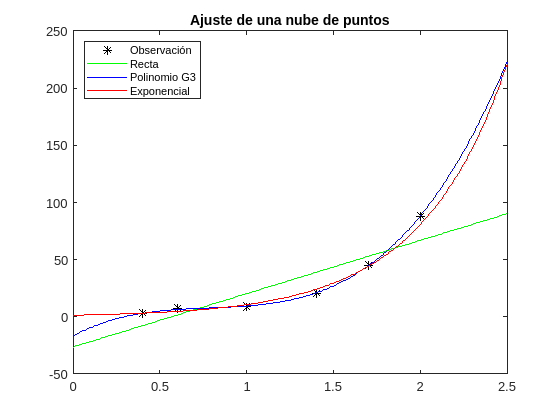

% Iniciar una figura pintando solo los puntos en negro
figure(1)
plot(X,Y,'*k'); hold on; 

% Crear un vector de valores para evaluar el polinomio de forma continua para la representación
x=0:0.01:2.5;
y1=polyval(p1,x);
y3=polyval(p3,x); 
plot(x,y1,'g') % Recta de ajuste en verde
plot(x,y3,'b') % Curva de ajuste de grado 3 en azul
plot(x,A*exp(B*x),'r') % Curva de ajuste del tipo exponencial en rojo
legend('Observación','Recta','Polinomio G3','Exponencial', 'Location','northwest')
title('Ajuste de una nube de puntos')
hold off 

Con estas gráficas parece evidente que se ajusta mejor el polinomio de tercer grado, además el error cuadrático cometido era el menor para ese ajuste.

#### **Ejercicio 4: Ajuste de una función por un polinomio**

Sea la función $f(x)=3x^2$. Hallar la recta que mejor la aproxima en el intervalo [0,2]  y hacer una  representación gráfica de ambas funciones. 

En primer lugar, ajustamos la función por mínimos cuadrados usando la función `polyfit`:

x1=linspace(0,2);
y1=3*x1.^2;
pol=polyfit(x1,y1, 1) 

pol =     6.0000   -1.9798


Por lo tanto, la ecuación de la recta aproximadora es: $y=6x-1.98$

Representamos la parábola y la recta, para ello hay que usar `polyval`, para hallar los valores de las ordenadas de la recta:

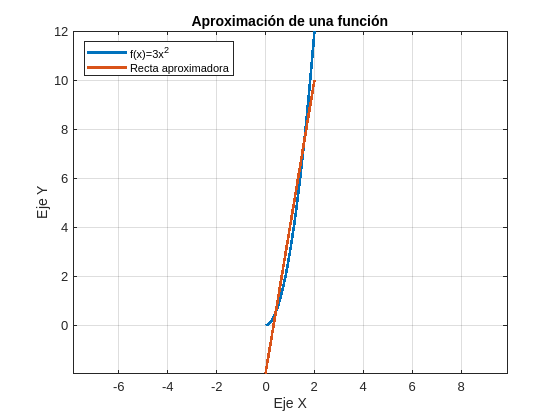

y2=polyval(pol, x1);
figure(1),
plot(x1, y1, x1, y2, 'LineWidth', 2)
xlabel('Eje X'), ylabel('Eje Y')
legend('f(x)=3x^2', 'Recta aproximadora', 'Location','NorthWest')
grid on
axis equal
title('Aproximación de una función')

### Ejercicios propuestos

Se propone resolver con MATLAB los ejercicios de las hojas de problemas del tema 4, en especial: 

- **4.6, 4.7, 4.8** utilizando la matriz de proyeccion y comprobar que se cumplen sus propiedades y que se obtiene la misma matriz a partir de una base ortonormal y otra no ortonormal del subespacio.

- **4.9, 4.10.**